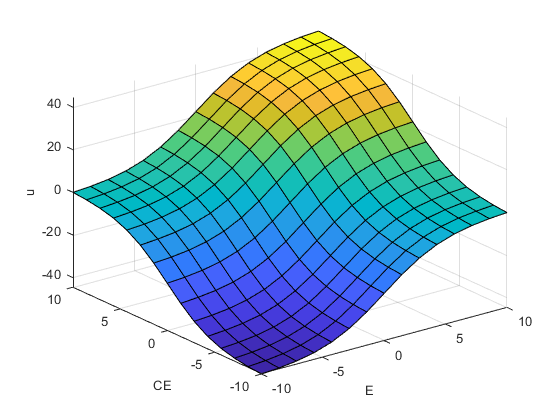

FIS = sugfis;
FIS = addInput(FIS,[-10 10],'Name','E');
FIS = addMF(FIS,'E','gaussmf',[7 -10],'Name','Negative');
FIS = addMF(FIS,'E','gaussmf',[7 10],'Name','Positive');
FIS = addInput(FIS,[-10 10],'Name','CE');
FIS = addMF(FIS,'CE','gaussmf',[7 -10],'Name','Negative');
FIS = addMF(FIS,'CE','gaussmf',[7 10],'Name','Positive');
FIS = addOutput(FIS,[-46 46],'Name','u');
FIS = addMF(FIS,'u','constant',-46,'Name','Min');
FIS = addMF(FIS,'u','constant',0,'Name','Zero');
FIS = addMF(FIS,'u','constant',46,'Name','Max');
ruleList = [1 1 1 1 1;...   % Rule 1
            1 2 2 1 1;...   % Rule 2
            2 1 2 1 1;...   % Rule 3
            2 2 3 1 1];     % Rule 4
FIS = addRule(FIS,ruleList);
gensurf(FIS)